**Paraméterek**

Meg kell adni, hogy hányadik oszlopban lévő törzseket szeretnénk vizsgálni. Az alábbi változókat kell megadni:

- ido - ahány időpillanat van

- tablazat - ebből olvassa be az adatokat, egyelőre csak 1 excelt tud beolvasni

- intervallum - excelben ezeket a cellákat olvassa be

- munkalap - excelben erről a munkalapról olvas be

- torzs változók - ahányadik oszlopban van a vizsgálni kívánt törzs

- torzsx_nev változók - törzsek neve

A program 2 féle módban tud működni. 1-es módban OD-t kell beolvasni és az alapján működik, amit Tünde prezentált Esztergomban. 2-es módban fluoreszcencia értékeket vizsgál.

clear;
clc;
close all;
ido=linspace(0,25.5,52); %time

comma=' , ';
torzs3_nev=strcat(torzs1_nev,comma, torzs2_nev);
tablazat1='OD_osszesitve';
tablazat2='mCh_osszesitve';
vizsgalat=1;% 1 - OD, 2- fluoreszcencia
intervallum='B1:S53';
if vizsgalat==1
    torzs1_nev='Y55 GFP'; %Y55 törzs
    torzs2_nev='W303 mCh'; %W303 törzs
    munkalap=3;
    torzs1=2; %strain1
    torzs2=6; %strain2
    torzs3=17; %mixed
    [data,txt,raw]=xlsread(tablazat1,munkalap,intervallum);
else
    torzs1_nev='W303 mCh'; %mCh-s törzs
    torzs2_nev='Y55 GFP'; %GFP-s törzs
    munkalap_1=5; %GFP
    munkalap_2=5; %mCh
    torzs1=6; %mCh
    torzs2=2; %GFP
    torzs3=17; %mixed
    [data,txt,raw]=xlsread(tablazat1,munkalap_1,intervallum);
    GFP=data;
    [data,txt,raw]=xlsread(tablazat2,munkalap_2,intervallum);
    mCh=data;
end
parameters=nan([1,8]); %egyedi parameterek, 3db torzs1, 3db torzs2

**Az 1. törzs paramétereinek becslése**

x0 változóban vannak a kezdeti értékek. Növekedési ráta, környezeti hatás, görbe kezdeti értéke. Ydata változóba olvassa be a program a növekedési görbe pontjait. A becsült paraméterek a parameters változóba kerülnek.

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          39.4647         
     1            4          34.0707         initial simplex
     2            6          23.5205         expand
     3            7          23.5205         reflect
     4            9          15.6493         expand
     5           11          14.0344         expand
     6           12          14.0344         reflect
     7           14          14.0344         contract outside
     8           15          14.0344         reflect
     9           16          14.0344         reflect
    10           18          13.4695         contract inside
    11           19          13.4695         reflect
    12           21          13.4695         contract outside
    13           22          13.4695         reflect
    14           24          13.4108         contract outside
    15           26          13.2323         reflect
    16           28          13.2323         contract inside
 

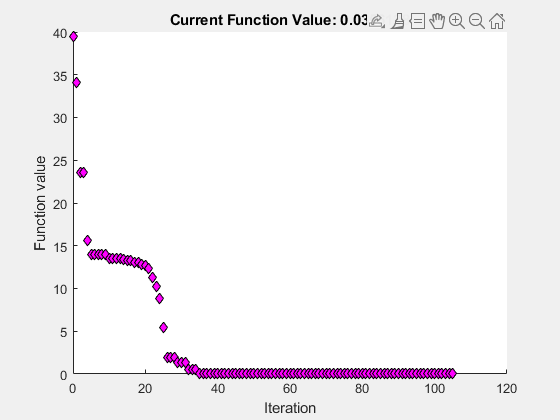

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



x0=[1, -0.5, 0.005];
if vizsgalat==1
    Ydata=data(:,torzs1);
else
    Ydata=mCh(:,torzs1);
end
Ydata=Ydata';
fun= @(x)fuggveny(x, ido, Ydata) ;
options=optimset('MaxIter',300, 'Display','iter', 'PlotFcns',@optimplotfval); %max iteráció szám
[x,fval,exitflag,output] = fminsearch(fun,x0, options);

parameters(1,1:3)=x;

Az 1. törzs ábrázolása

A megkapott paraméterekkel ábrázolja az eredeti adatsort és az illesztett görbét.

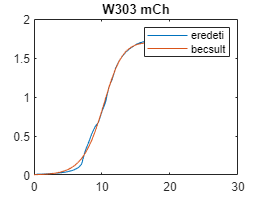

figure;
plot(ido,Ydata);
hold on;
ydata=nan([1,52]);
ydata(1)=parameters(3);
for t=2:52
    ydata(t)=ydata(t-1)+ydata(t-1)*(parameters(1)+parameters(2)*ydata(t-1));
end
plot(ido, ydata);
eredeti_1=Ydata;
becsult_1=ydata;
legend('eredeti', 'becsult');
title(torzs1_nev);
hold off;

**Az 2. törzs paramétereinek becslése**

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          35.8444         
     1            4          30.8884         initial simplex
     2            6          21.2557         expand
     3            7          21.2557         reflect
     4            9           14.727         expand
     5           11          13.6046         reflect
     6           12          13.6046         reflect
     7           14          13.6046         contract outside
     8           16          13.6046         contract inside
     9           18          13.6046         contract inside
    10           20          13.5201         reflect
    11           22          13.1312         expand
    12           23          13.1312         reflect
    13           25           12.744         expand
    14           27          12.6238         reflect
    15           29          12.0621         expand
    16           31          11.6357         reflect
    17           33  

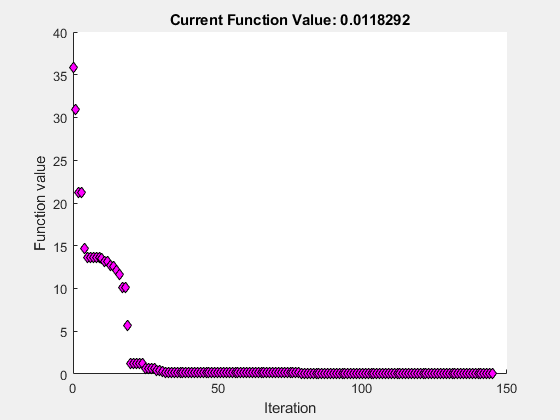

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



x0=[1, -0.5, 0.005]; %kezdeti érték paraméterre - növekedési ráta,környezet eltarto kepessege, kezdeti ertek
if vizsgalat==1
    Ydata=data(:,torzs2);
else
    Ydata=GFP(:,torzs2);
end
Ydata=Ydata';
fun= @(x)fuggveny(x, ido, Ydata) ;
options=optimset('MaxIter',300, 'Display','iter', 'PlotFcns',@optimplotfval); %max iteráció szám
[x,fval,exitflag,output] = fminsearch(fun,x0, options);

parameters(1,4:6)=x;

A 2. törzs ábrázolása

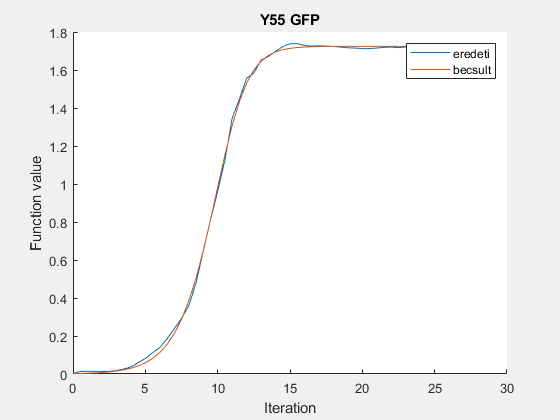

figure(2);
plot(ido,Ydata);
hold on;
ydata=nan([1,52]);
ydata(1)=parameters(6);
for t=2:52
    ydata(t)=ydata(t-1)+ydata(t-1)*(parameters(4)+parameters(5)*ydata(t-1));
end
plot(ido, ydata);
eredeti_2=Ydata;
becsult_2=ydata;
legend('eredeti', 'becsult');
title(torzs2_nev);
hold off;

**A kevert kolónia paramétereinek becslése**

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          74.8324         
     1            3          74.8324         initial simplex
     2            5          74.6882         expand
     3            7          74.3091         expand
     4            9          73.8285         expand
     5           11           72.841         expand
     6           13          71.3804         expand
     7           15          68.7332         expand
     8           17          64.5212         expand
     9           19          57.5076         expand
    10           21           46.367         expand
    11           23          30.3712         expand
    12           25          11.5776         expand
    13           27          1.73552         expand
    14           29          0.21349         expand
    15           31        0.0269764         expand
    16           32        0.0269764         reflect
    17           34        0.0269764         contract o

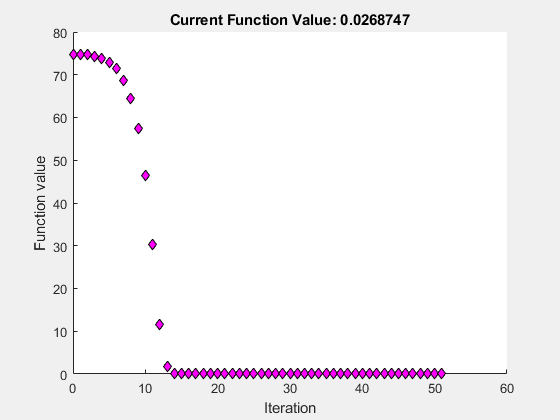

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



c0=[0,0];
if vizsgalat==1
    Ydata=data(:,torzs3);
    Ydata=Ydata';
    fun= @(x)fuggveny_3(x, ido, Ydata, parameters) ;
else
    Ydata_1=mCh(:,torzs3);
    Ydata_1=Ydata_1';
    Ydata_2=GFP(:,torzs3);
    Ydata_2=Ydata_2';
    fun= @(x)fuggveny_2(x, ido, Ydata_1, Ydata_2, parameters) ;
end
options=optimset('MaxIter',200, 'Display','iter', 'PlotFcns',@optimplotfval); %max iteráció szám
[x,fval,exitflag,output] = fminsearch(fun,c0 , options);

c=x; %kereszthatas
parameters(1,7:8)=c;

A kevert kolónia ábrázolása

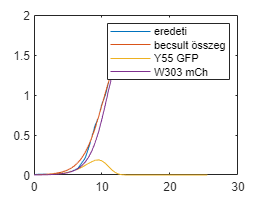

figure(3);
if vizsgalat==1
    plot(ido,Ydata);
    hold on;
    ydata_1=nan([1,52]);
    ydata_1(1)=parameters(3)/2;
    ydata_2=nan([1,52]);
    ydata_2(1)=parameters(6)/2;
    for t=2:52
        ydata_2(t)=ydata_2(t-1)+ydata_2(t-1)*(parameters(4)+parameters(5)*ydata_2(t-1)+c(2)*ydata_1(t-1));
        ydata_1(t)=ydata_1(t-1)+ydata_1(t-1)*(parameters(1)+parameters(2)*ydata_1(t-1)+c(1)*ydata_2(t-1));
    end
    plot(ido, ydata_1+ydata_2);
    plot(ido, ydata_1);
    plot(ido, ydata_2);
    legend('eredeti', 'becsult összeg', torzs1_nev, torzs2_nev);
    hold off;
else
    plot(ido,Ydata_1);
    hold on;
    plot(ido,Ydata_2);
    ydata_1=nan([1,52]);
    ydata_1(1)=parameters(3)/2;
    ydata_2=nan([1,52]);
    ydata_2(1)=parameters(6)/2;
    for t=2:52
        ydata_2(t)=ydata_2(t-1)+ydata_2(t-1)*(parameters(4)+2*parameters(5)*ydata_2(t-1)+c(2)*ydata_1(t-1));
        ydata_1(t)=ydata_1(t-1)+ydata_1(t-1)*(parameters(1)+2*parameters(2)*ydata_1(t-1)+c(1)*ydata_2(t-1));
    end
    plot(ido, ydata_1);
    plot(ido, ydata_2);
    legend(strcat('eredeti ',torzs1_nev), strcat('eredeti ',torzs2_nev), strcat('becsult ',torzs1_nev), strcat('becsult ',torzs2_nev), 'Location','northwest');
    hold off;
end

**Kapott paraméterek: **

parameters: mCh növekedési ráta, környezet eltartóképessége, kiindulási érték, GFP növekedési ráta, környezet eltartóképessége, kiindulási érték, y2(GFP) hatása az y1 (mCh)-re, y1 (mCh) hatása az y2-re (GFP)

c

c =    -0.6863    0.1252


parameters'

ans =     0.3401
   -0.1993
    0.0039
    0.4021
   -0.2331
    0.0021
   -0.6863
    0.1252
